# ROM Ph.D. Playground

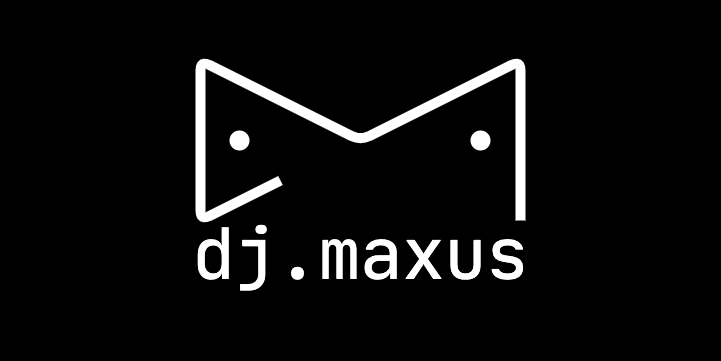

## Startup

startup;

## Dynamical System

### General Description


$$\dot{u} = f(u,t,q;\kappa)$$


- $u(t)$— unknown state vector

- $q(t)$— actuation (control) vector of arbitrary dimensionality

- $\kappa$ — system parameters: static properties, (maybe) including initial and boundary conditions

If actuation is applied directly to the ODE and system itself does not evolve


$$\dot{u} = f(u;\kappa) + q(t)$$


### Fundamental Solution

Generalization of solution over $q(t)$


$$G(t;\tau): \dot{G}(t;\tau) = f(u;\kappa)+I \delta(t-\tau)$$


$I$— identity matrix

### Discrete System

#### Finite Differece Equation


$$u_{n+1} = f(u_{n};\kappa) + q_{n+1}$$


$f$ may be an implicit function

#### Fundamental solution

For linear system with constant actuation


$$u_{n+1} = Fu_{n} + q$$


Spectral decomposition 

- 
$$F \Psi = \Psi \Lambda$$


- 
$$u_n = \Psi v_n$$


- 
$$q = \Psi p$$



$$v_{n+1} = \lambda v_n + p$$


if actuation started from step $m$


$$v_n = \lambda^n v_0 + p \sum_{k=m}^{n-1}\lambda^k = \lambda^n v_0 + p\frac{\lambda^m - \lambda^n}{1 - \lambda}$$


For non-constant actuation


$$v_{n+1} = \lambda v_n + p_{n+1}$$



$$v_n = \lambda^n v_0 + \sum_{1}^{k=n} p_k \lambda^{n-k} $$


## PDE Settings

Nonlinear diffusion


$$\dot{u} + \overrightarrow{\nabla}(\kappa(u)\nabla u) = \dots$$


- Dimensionality $N_x$

Nx = 1000;

- Diffusion 

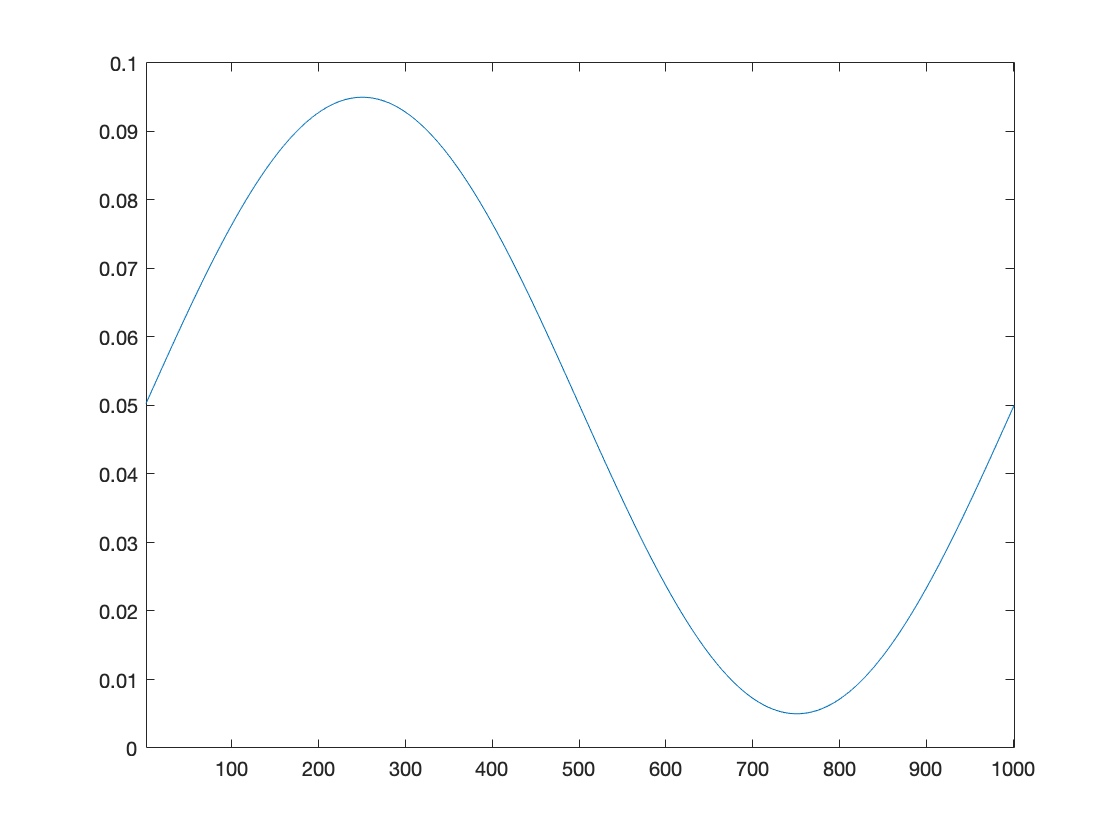

k =0.1; D  = genDiffusion(Nx,0.9,1,0.5e-1, @(u) [1+u^2*k,2*u*k]);

plot(1:(Nx+1),D.val); xlim([1,Nx+1]); % plot

- Boundary & Initial Conditions

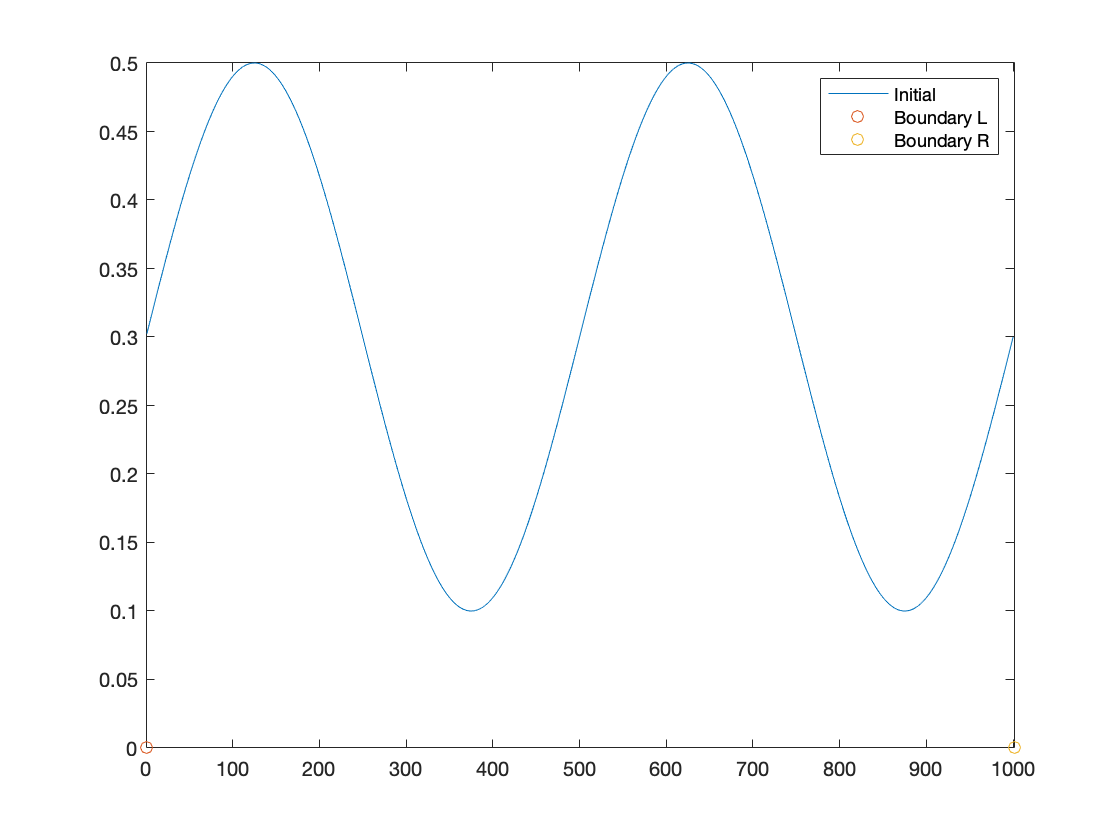

bc = genBC(1,[0,0]);
x0 = genInit(Nx,0.2,2,0.3);

plot(1:Nx,x0,'-',0,bc.val(1),'o',Nx+1,bc.val(2),'o');
xlim([0,Nx+1]); legend({'Initial','Boundary L','Boundary R'});

Problem Constructors

- FOM

makeFOM = @(q,name) genProblem(name,Nx,genParam(D,bc,q),x0);

- ROM-I

makeROM_I = @(name,q,encoder) genProblem(name,Nx,genParam(D,bc,q),x0,encoder);

- ROM-II

makeROM_II = @(name,q,encoder,nfa) genProblem(name,Nx,genParam(D,bc,q),x0,encoder,nfa.res,nfa.jac);

## ODE settings

- Endtime $T$

T = 1;

- Number of timesteps $N_t$

Nt = 100;

- Timestep $\tau = \frac{T}{N_t}$

dt = T/Nt;

## Nonlinear  Solver Settings

- Convergence Criteria

newton_param = struct(...
    'iters'    , 10,...
    'iters_min', 3,...
    'tol'      , 1e-3,...
    'tol_rel'  , 1e-3,...
    'tol_g'    , 1e-3,...
    'tol_rel_g', 1e-3 ...
    );

- Newton solver

nlin_newton = @(x,Res,Jac) newton      (x,Res,Jac,newton_param);

- Newton — Gauss solver

nlin_gauss  = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param);

### FOM

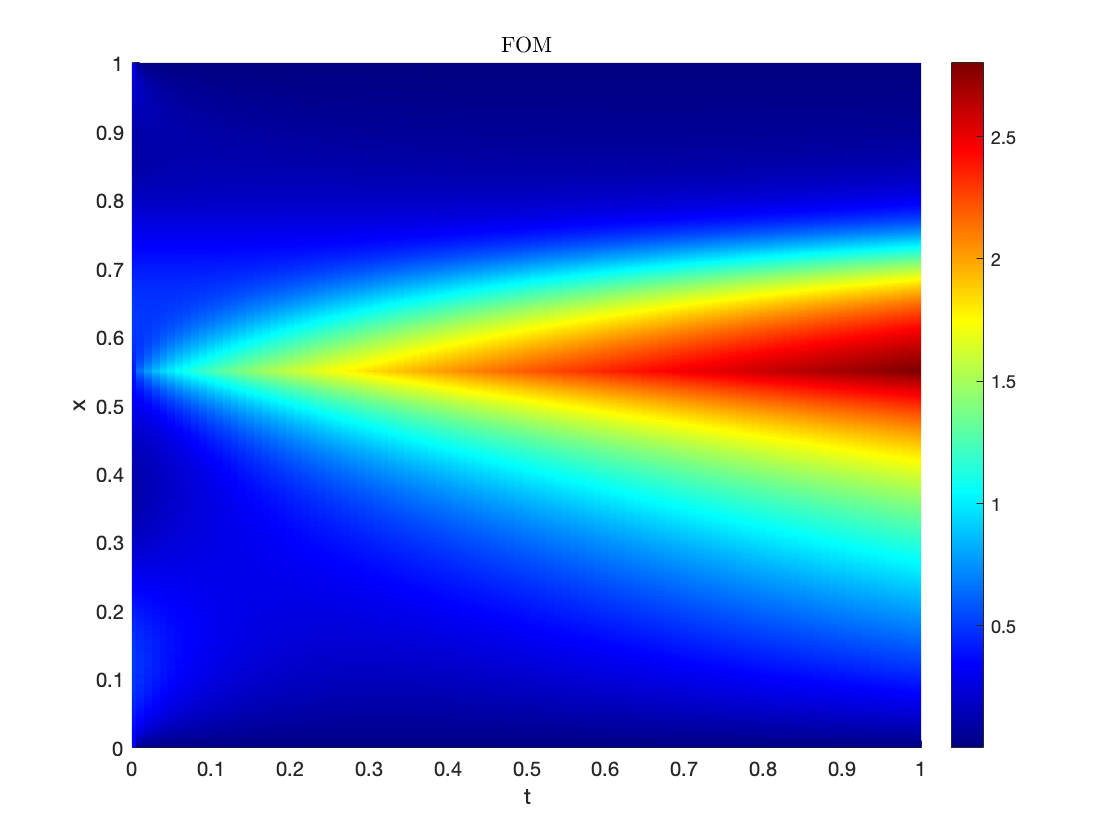

q = genSource(Nx,0.55,1e+3);
FOM = solveDif(T,Nt,makeFOM(q,'FOM'),nlin_newton);
plotSol(axes(figure),FOM);

### ROM

Collect Data

[X,W,Jw] = collectSolData(FOM);

#### POD

Train Encoder

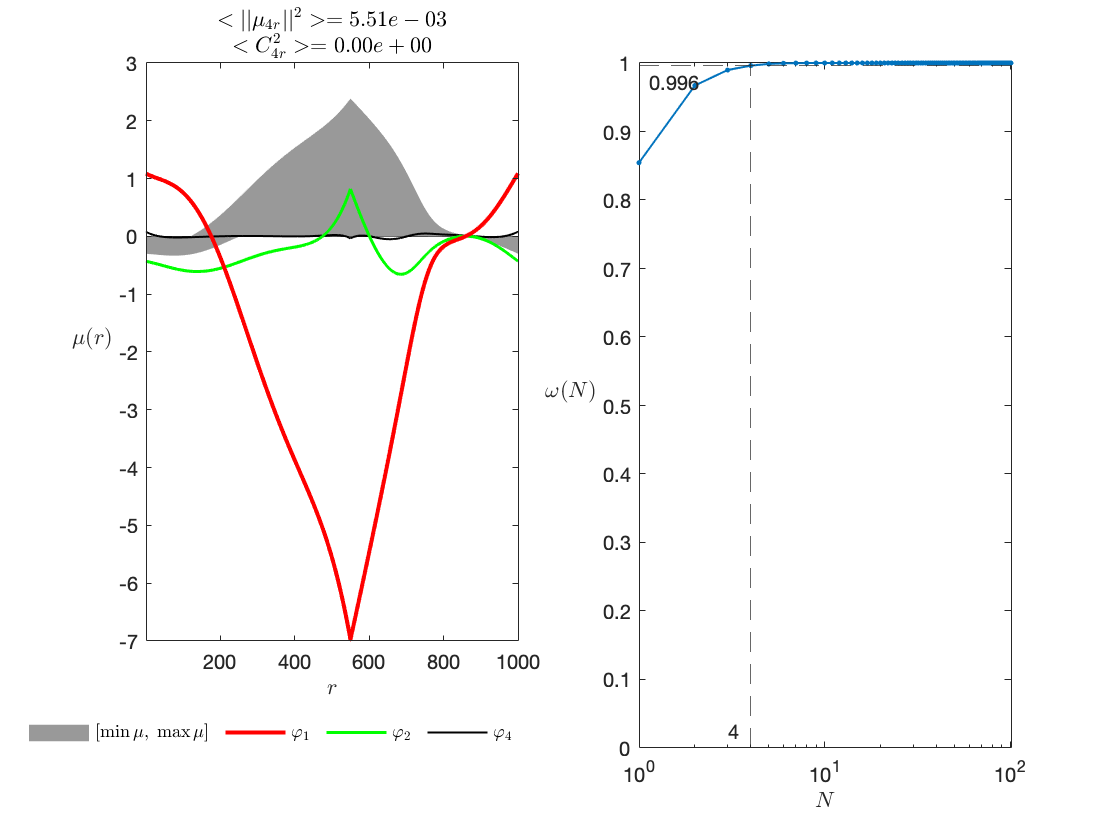

en_crit = 0.99;
pod = PCA(X, en_crit, 'init', x0);
pod.plotSummary(figure);

#### ROM-I

Perfom POD-ROM Calculation

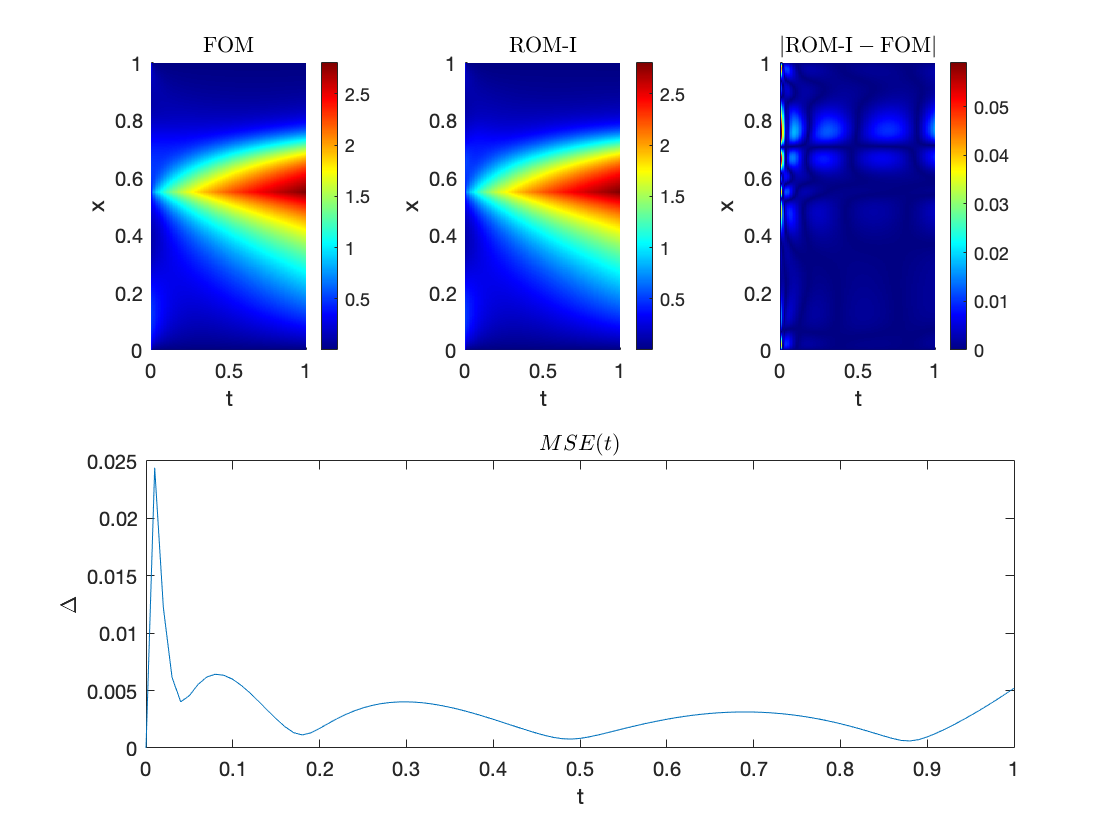

encoder = pod.genEncoder();

ROM.I = makeROM_I('ROM-I',q,encoder);
ROM.nlin = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param, encoder.decjac);

ROM.I = solveDif(T,Nt,ROM.I,ROM.nlin);
ROM.I.X = encoder.decode(ROM.I.X);
plotComp(figure(),FOM,ROM.I);

#### GAPPY-POD

POD for nonlinear functions

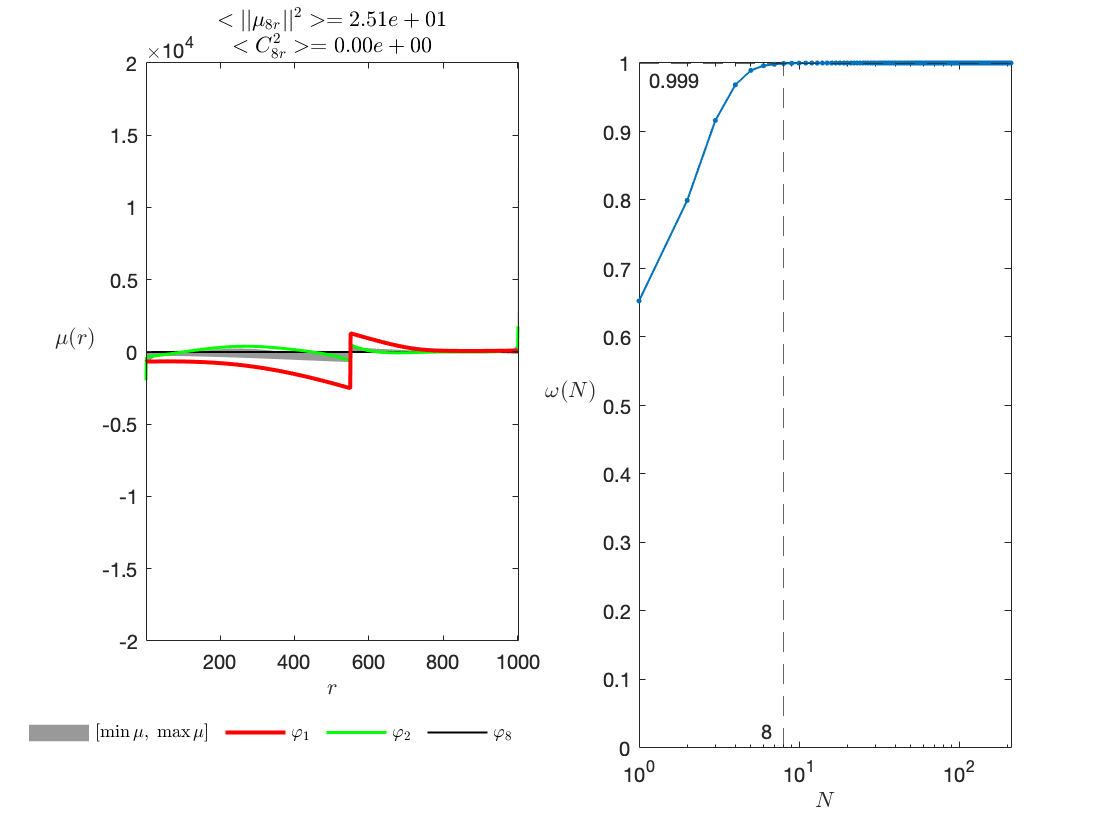

N1 = floor(pod.npc() * 2);
gappy.init = zeros(Nx+1,1);
gappy.R = PCA( W, N1,'init', gappy.init);
gappy.J = PCA(Jw, N1,'init', gappy.init);
gappy.R.plotSummary(figure);

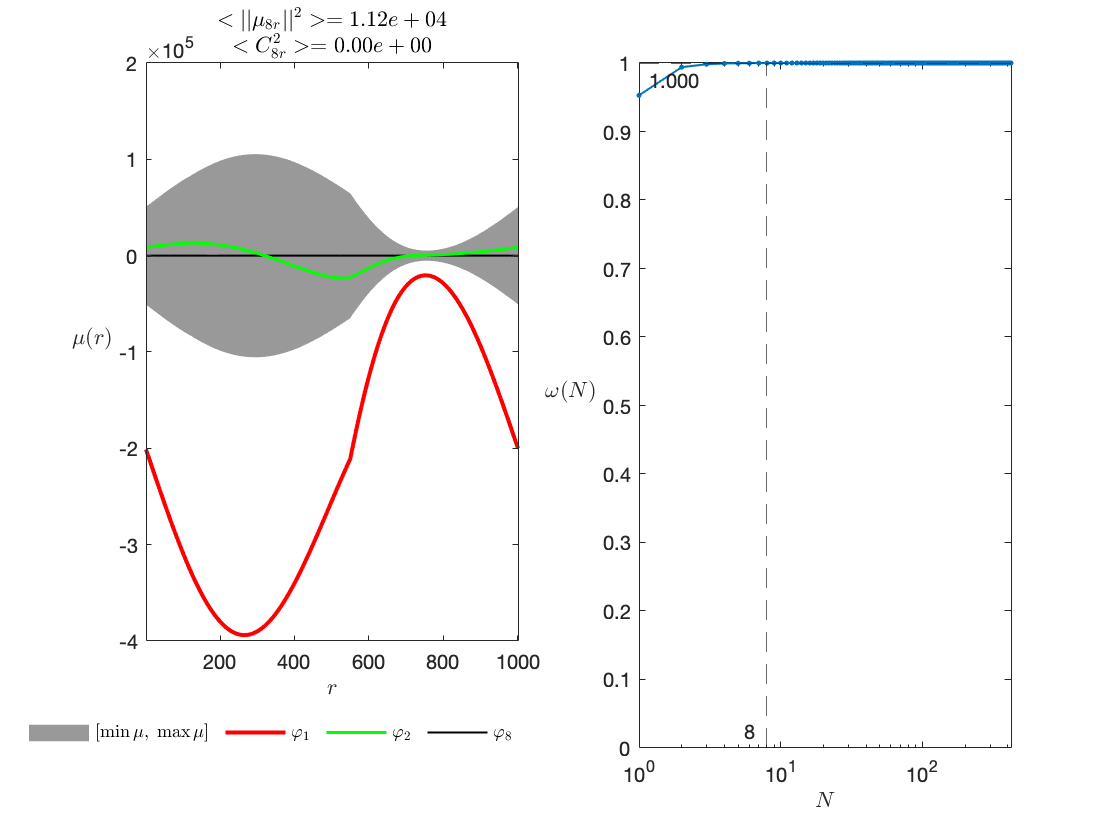

gappy.J.plotSummary(figure);

Gappy mask

N2 =floor(N1*2);
idx = unique([gappy.R.calcGreedy(N2),...
              gappy.J.calcGreedy(N2)]);
idx = unique([idx,1,Nx+1,q.pos]);
disp(idx);

  Columns 1 through 10

           1           2           3          18          19          38          39          56          57          99

  Columns 11 through 20

         100         154         155         265         266         307         308         418         419         524

  Columns 21 through 26

         525         549         550         551         552        1001



Gappy operators

gappy.R = gappy.R.buildGappy(idx);
gappy.J = gappy.J.buildGappy(idx);


Nonlinear Function Approximation

nfa.res = gappy.R.genNFA();
nfa.jac = gappy.J.genNFA();

#### ROM-II

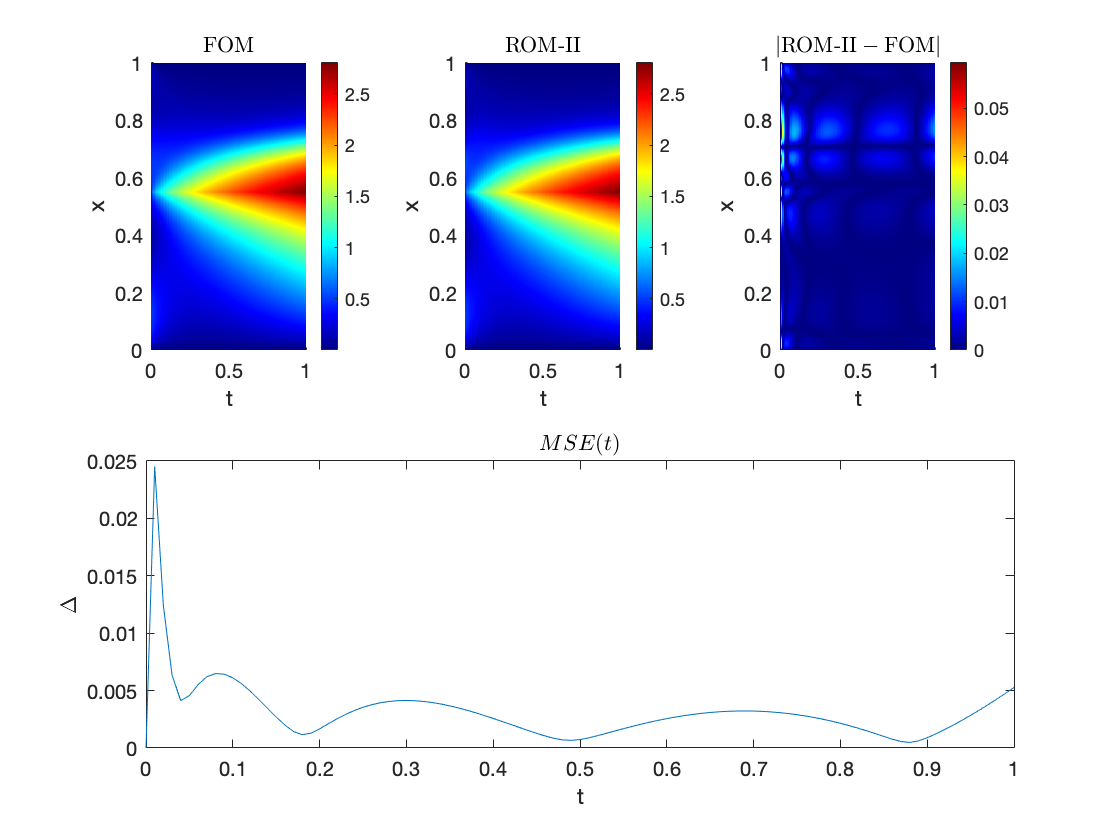

ROM.II = makeROM_II('ROM-II',q,encoder,nfa);
ROM.II = solveDif(T,Nt,ROM.II,ROM.nlin); % solve
ROM.II.X = encoder.decode(ROM.II.X); % decode solution
plotComp(figure,FOM,ROM.II);

## Experiments

### #1: Self-reconstruction of linear system

- Calculate $\text{FOM}(q_0)$ 

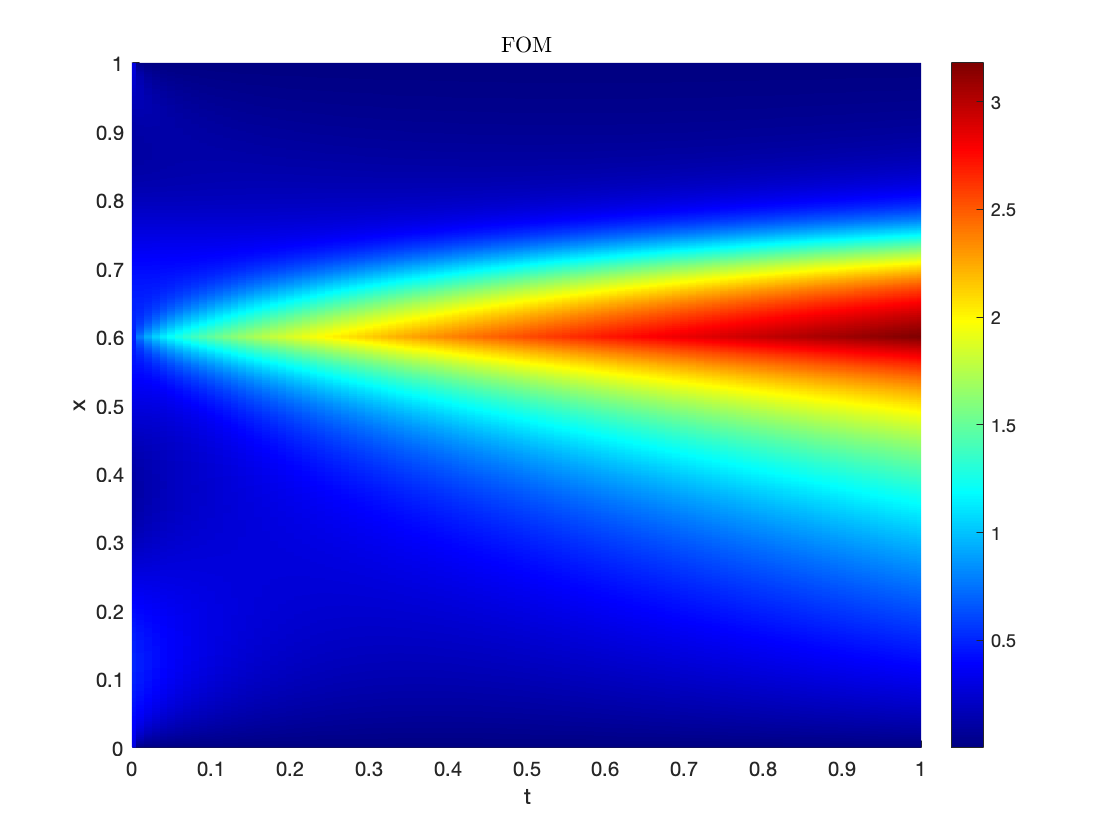

q_0 = genSource(Nx,0.6,1e+3);
FOM = makeFOM(q_0,'FOM');
FOM = solveDif(T,Nt,FOM,nlin_newton);
plotSol(axes(figure),FOM);

- Collect Data $D_0$

[X,~,~] = collectSolData(FOM);

- Calculate **reference** $\text{ROM}_1(D_0)$

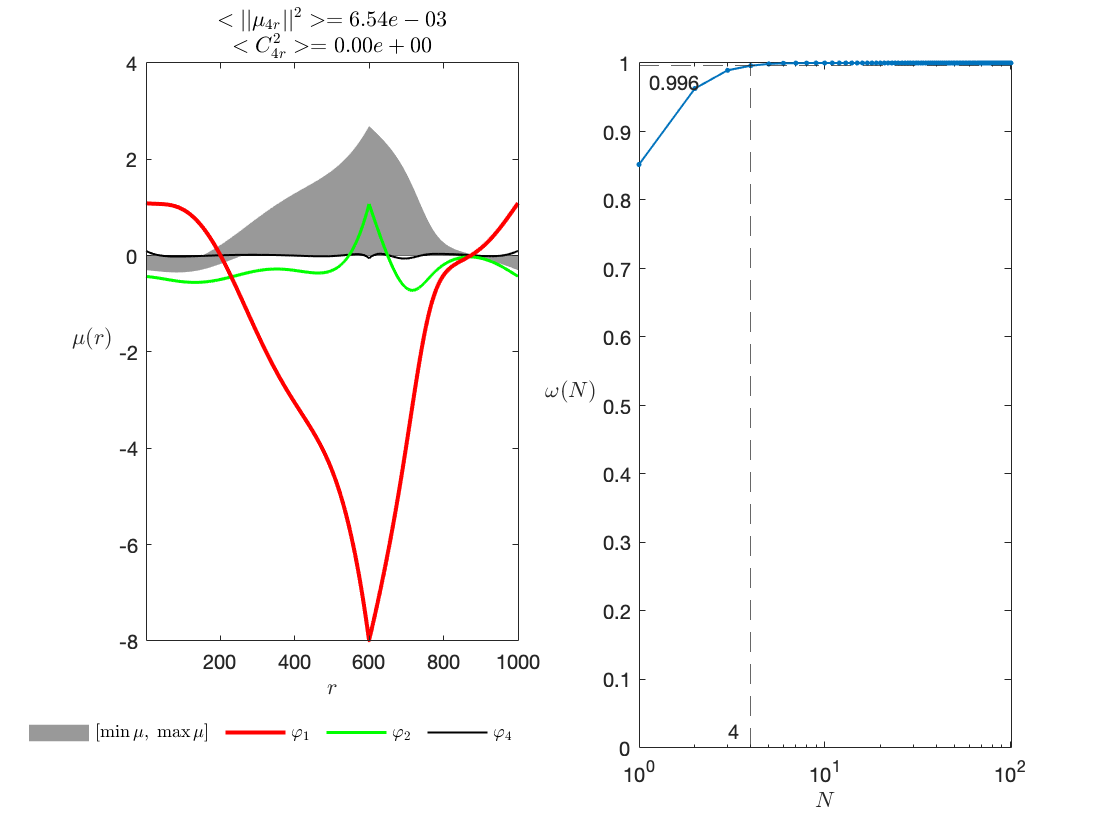

% Reference Encoder
en_crit = 0.99;
pod = PCA(X, en_crit, 'init', x0);
pod.plotSummary(figure);

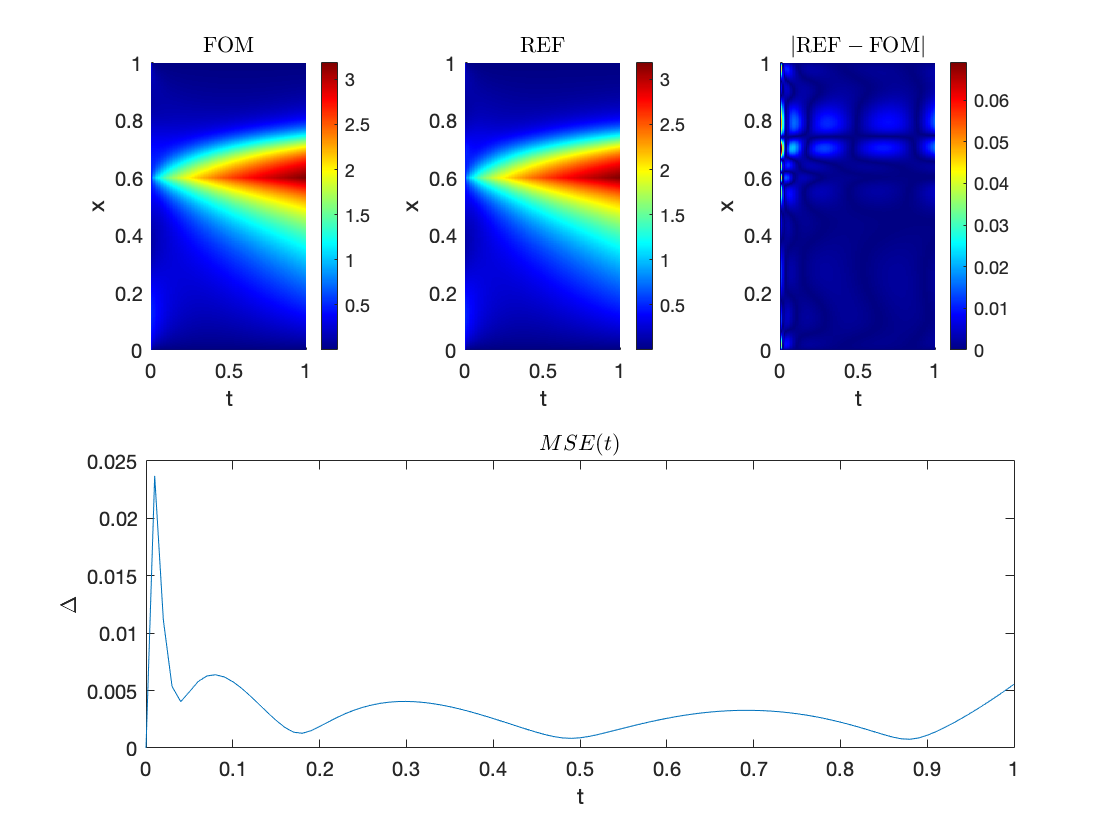

encoder = pod.genEncoder();

% nonlinear solver
nlin = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param, encoder.decjac);

% Reference ROM-I
REF = makeROM_I('REF',q_0,encoder);
REF = solveDif(T,Nt,REF,nlin);
REF.X = encoder.decode(REF.X);

plotComp(figure(),FOM,REF);

- Approximate linear $\text{ODE}$ from data $\text{DMD}(D_0)$


$$x_{n+1} = Lx_n + q$$


X1 = X(:,1:end-1);
X2 = X(:,2:end);

Q = repmat(full(FOM.param.q.val).*dt,1,Nt);
[L,Psi,Lambda] = dmds(X1,X2-Q,24);

- Calculate solution approximation using fundamental solution $\tilde{D}_0$

Y = calcGreenFDE(Psi,Lambda,Nt,x0,FOM.param.q.val.*dt);

- Calculate **test** $\text{ROM}_1(\tilde{D}_0)$

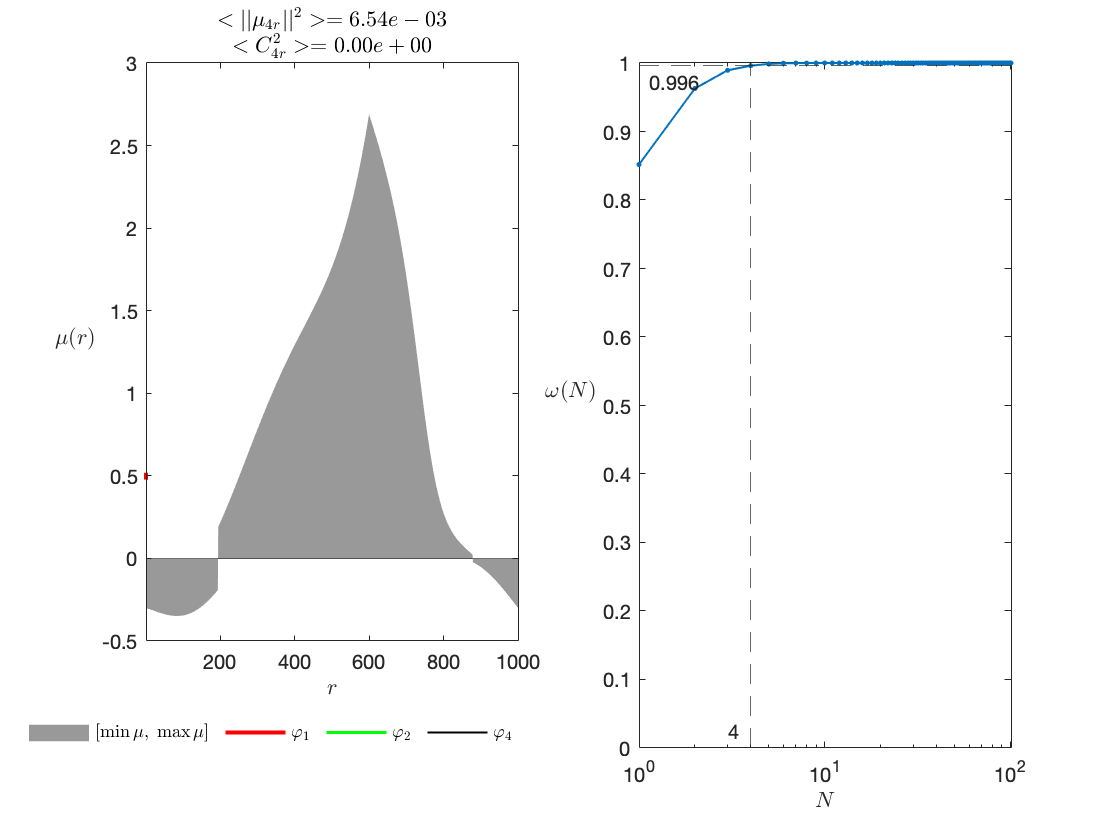

% Test Encoder
en_crit = 0.99;
pod_test = PCA(Y, en_crit, 'init', x0);
pod_test.plotSummary(figure);

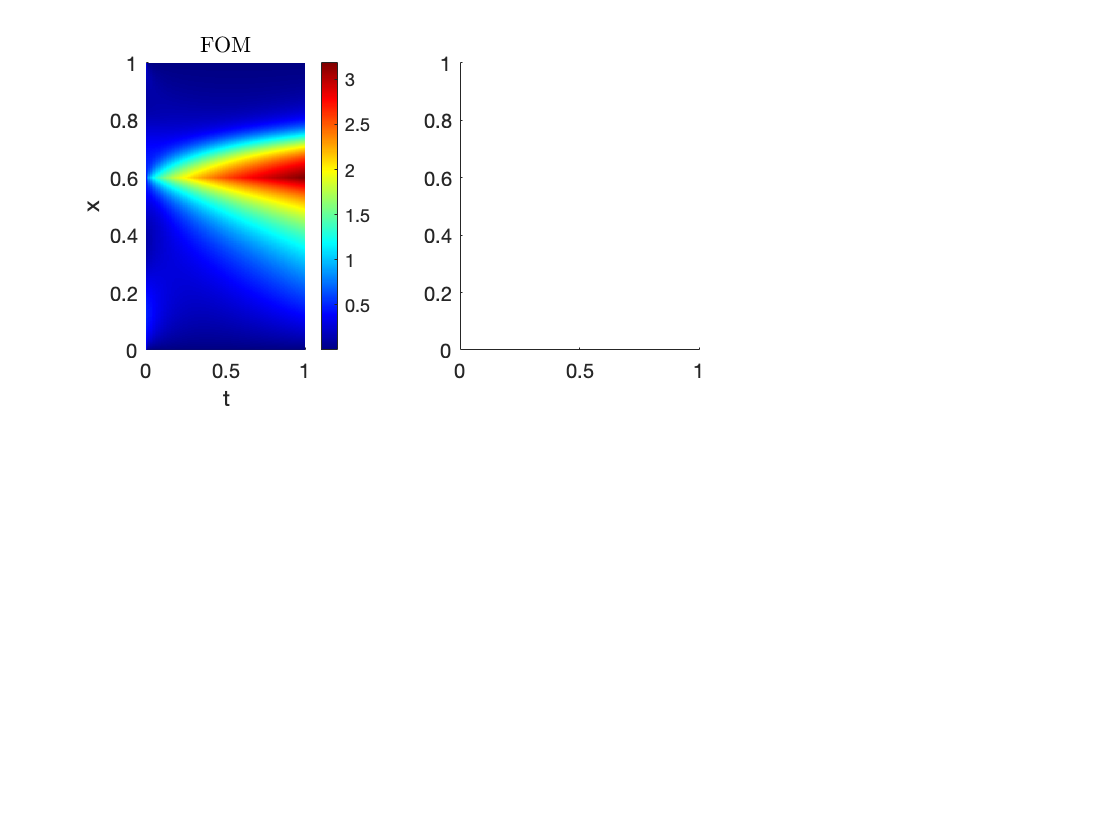

Error using image
Complex values are not supported.

Error in imagesc (line 52)
    hh = image(varargin{:}, 'CDataMapping', 'scaled');

Error in plotSol>plotSolFom (line 50)
    imagesc(ax,'CData',sol.X,'XData',sol.t,'YData',(1:Nx)./Nx);

Error in 


encoder_test = pod_test.genEncoder();
% nonlinear solver
nlin = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param, encoder_test.decjac);

% Reference ROM-I
TEST = makeROM_I('TEST',q_0,encoder_test);
TEST = solveDif(T,Nt,TEST,nlin);
TEST.X = encoder_test.decode(TEST.X);
plotComp(figure(),FOM,TEST);

- Compare $\tilde{D}_0,~D_0$ 

DMD = TEST;
DMD.X = Y;
plotComp(figure(),FOM,DMD);

- Compare $\text{ROM}_1(\tilde{D}_0),~\text{ROM}_1(D_0)$

plotComp(figure(),FOM,TEST);

### #2: Approximation of linear system

- Calculate reference $\text{FOM}(q_1)$ 

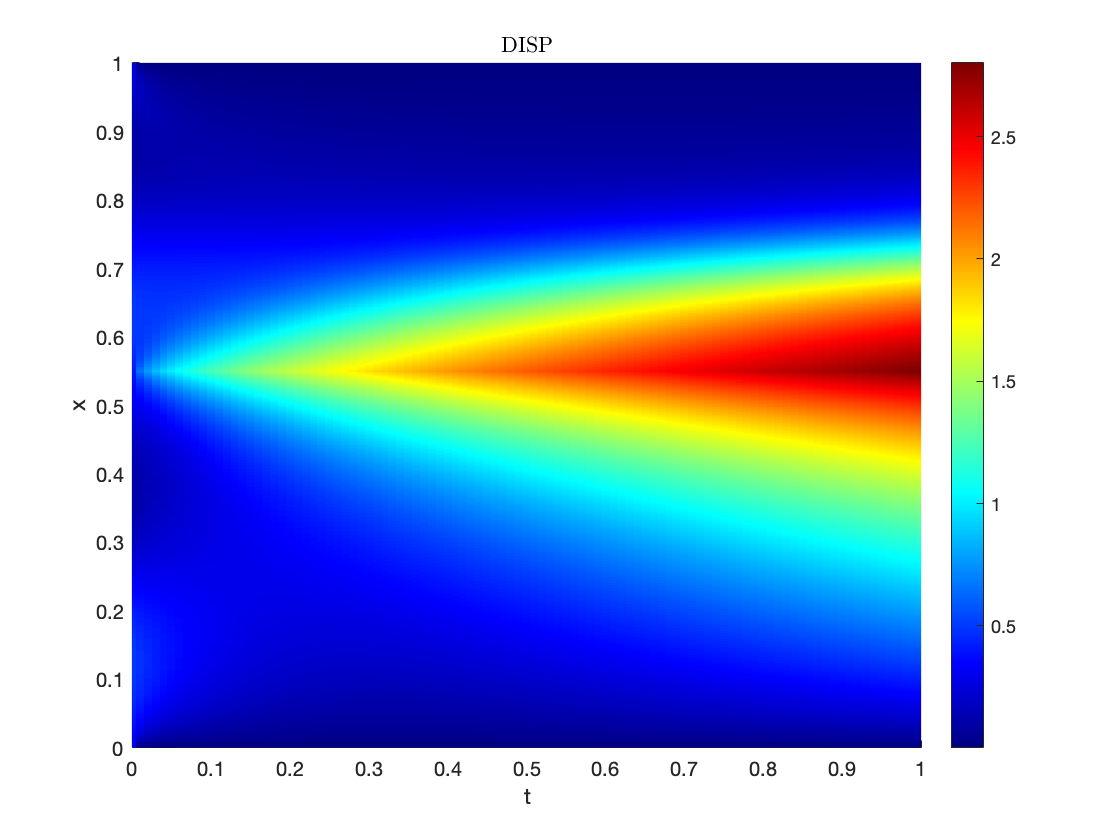

q_1 = genSource(Nx,0.55,1e+3);
DISP = makeFOM(q_1,'DISP');
DISP = solveDif(T,Nt,DISP,nlin_newton);
plotSol(axes(figure),DISP);

- Collect Data $D_1$

[D_1,~,~] = collectSolData(DISP);

- Calculate **reference** $\text{ROM}_1(D_1)$

% Reference Encoder
pod = PCA(D_1, en_crit, 'init', x0);
pod.plotSummary(figure);

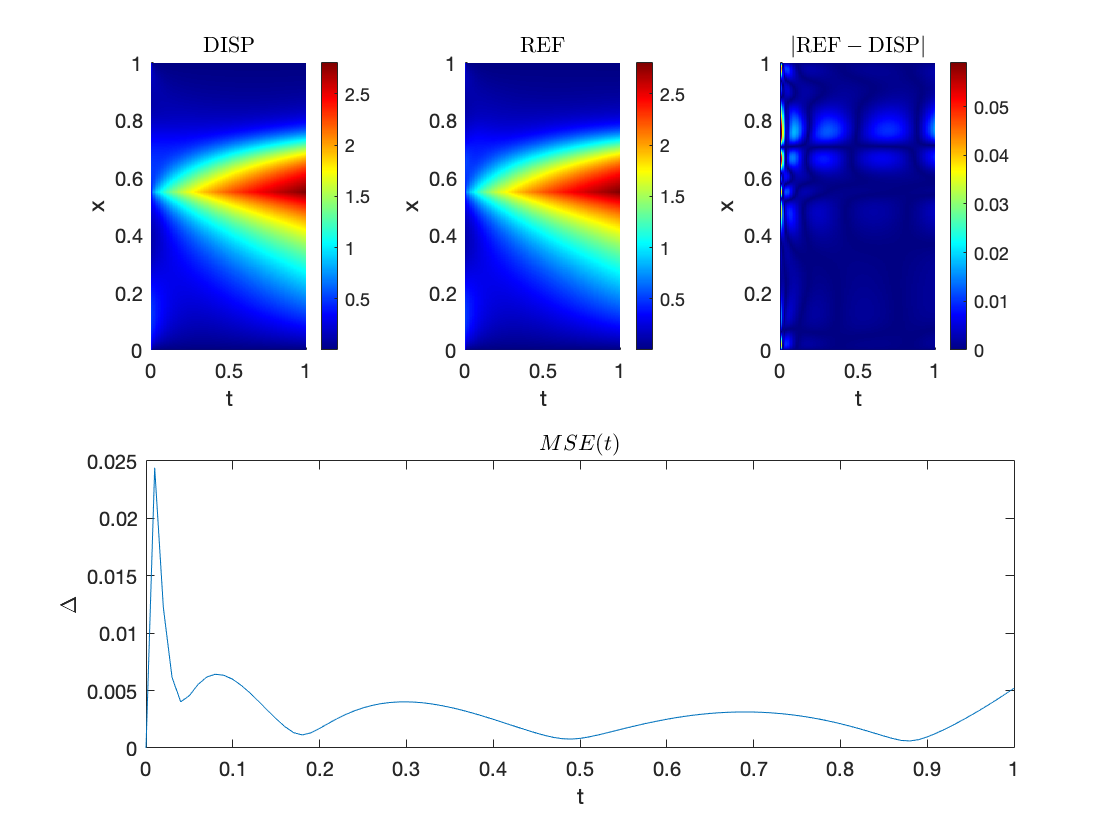

encoder = pod.genEncoder();

% nonlinear solver
nlin = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param, encoder.decjac);

% Reference ROM-I
REF = makeROM_I('REF',q_1,encoder);
REF = solveDif(T,Nt,REF,nlin);
REF.X = encoder.decode(REF.X);

plotComp(figure(),DISP,REF);

- Calculate another train data

e2.train.q = [0.5,0.6];
for i = 1:length(e2.train.q)
    e2.train.sol(i) = solveDif(T,Nt,...
        genProblem('TRAIN',Nx,genParam(genDiffusion(Nx,0.9,1,0.5e-1,@(u)([1,0])),...
                   bc,genSource(Nx,e2.train.q(i),1e+3)),x0),...
        nlin_newton);
    e2.train.data{i} = collectSolData(e2.train.sol(i));
end

X1 = [];
X2 = [];
Q = [];
for i = 1:2
    x = e2.train.data{i};
    X1 =[X1,x(:,1:end-1)];
    X2 =[X2,x(:,2:end)];
    sol = e2.train.sol(i);
    Q = [Q,repmat(full(sol.param.q.val).*dt,1,Nt)];
end

- Evaluate DMD for ODE

rank = 15;
[L,Psi,Lambda] = dmds(X1,X2-Q,rank);
Lambda(Lambda < 0) = 0;

- Calculate solution approximation using fundamental solution $\tilde{D}_1$

e2.G = calcGreenFDE(Psi,Lambda,Nt,x0,DISP.param.q.val.*dt);

- Calculate **test** $\text{ROM}_1(\tilde{D}_1)$

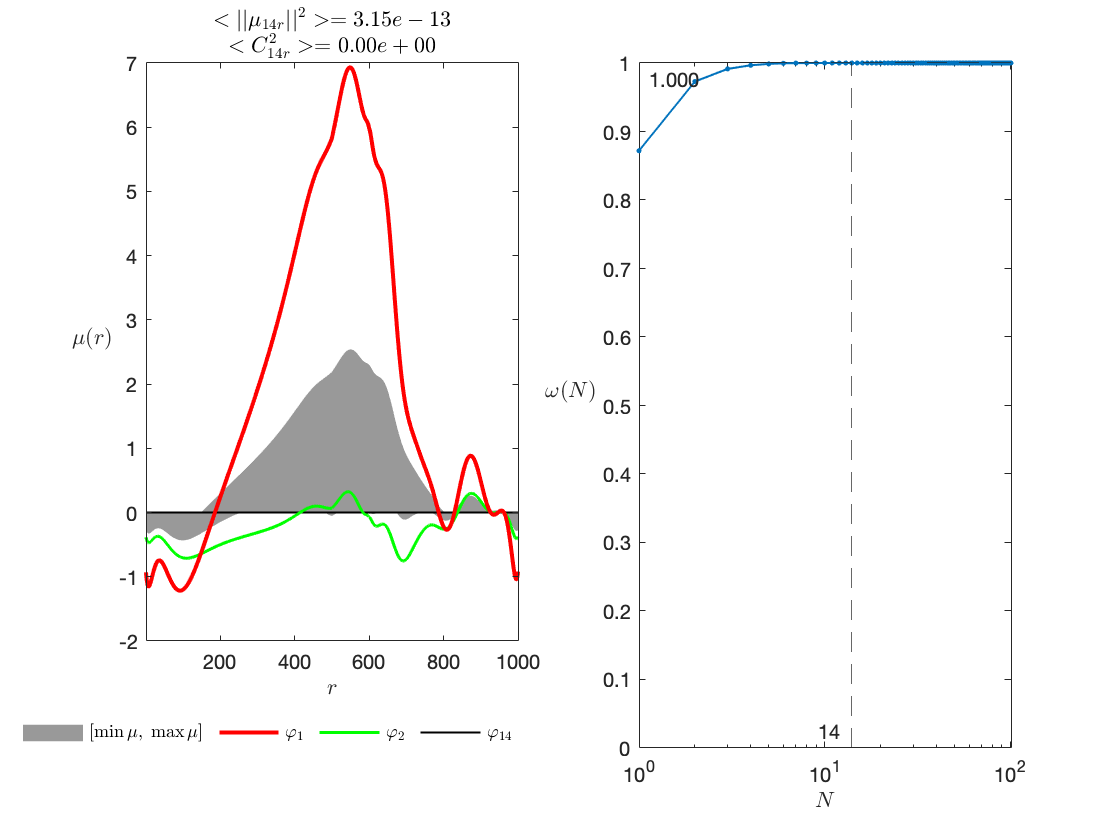

% Test Encoder
pod_test = PCA(real(e2.G), rank-1, 'init', x0);
pod_test.plotSummary(figure);

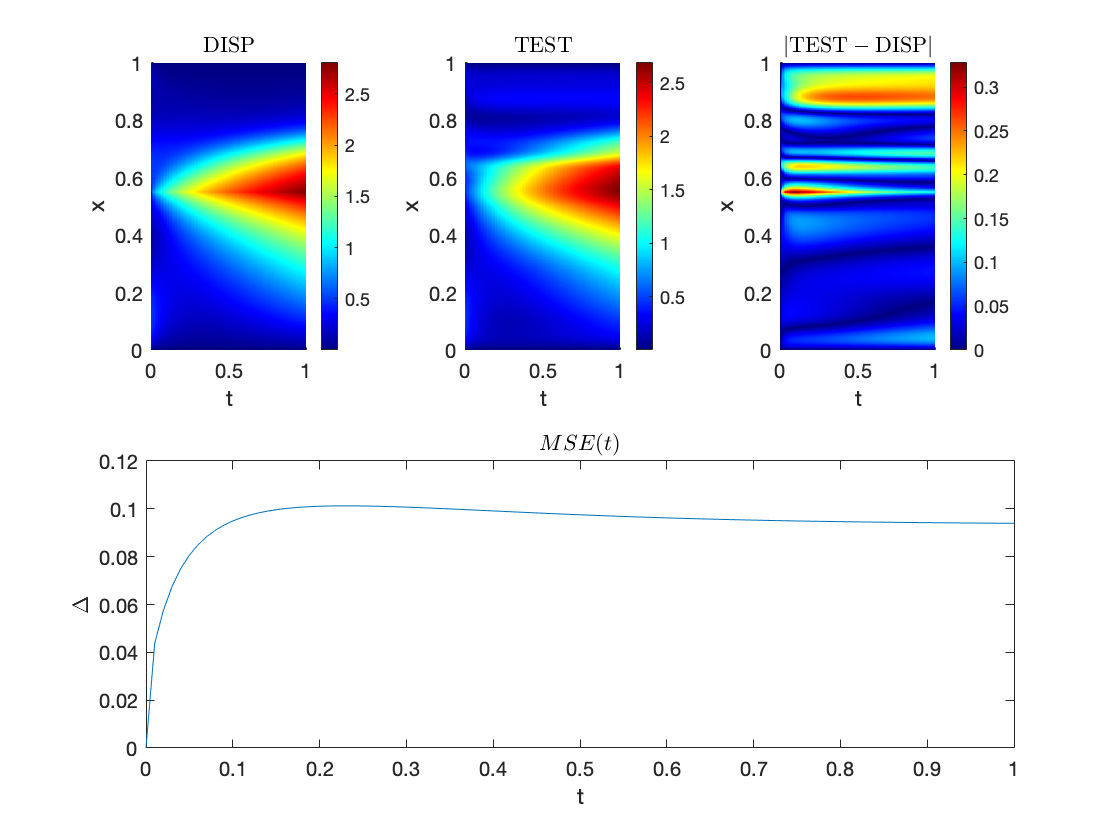


encoder_test = pod_test.genEncoder();
% nonlinear solver
nlin = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param, encoder_test.decjac);

% Reference ROM-I
TEST = makeROM_I('TEST',q_1,encoder_test);
TEST = solveDif(T,Nt,TEST,nlin);
TEST.X = encoder_test.decode(TEST.X);
plotComp(figure(),DISP,TEST);

- Compare $\tilde{D}_1,~D_1$ 

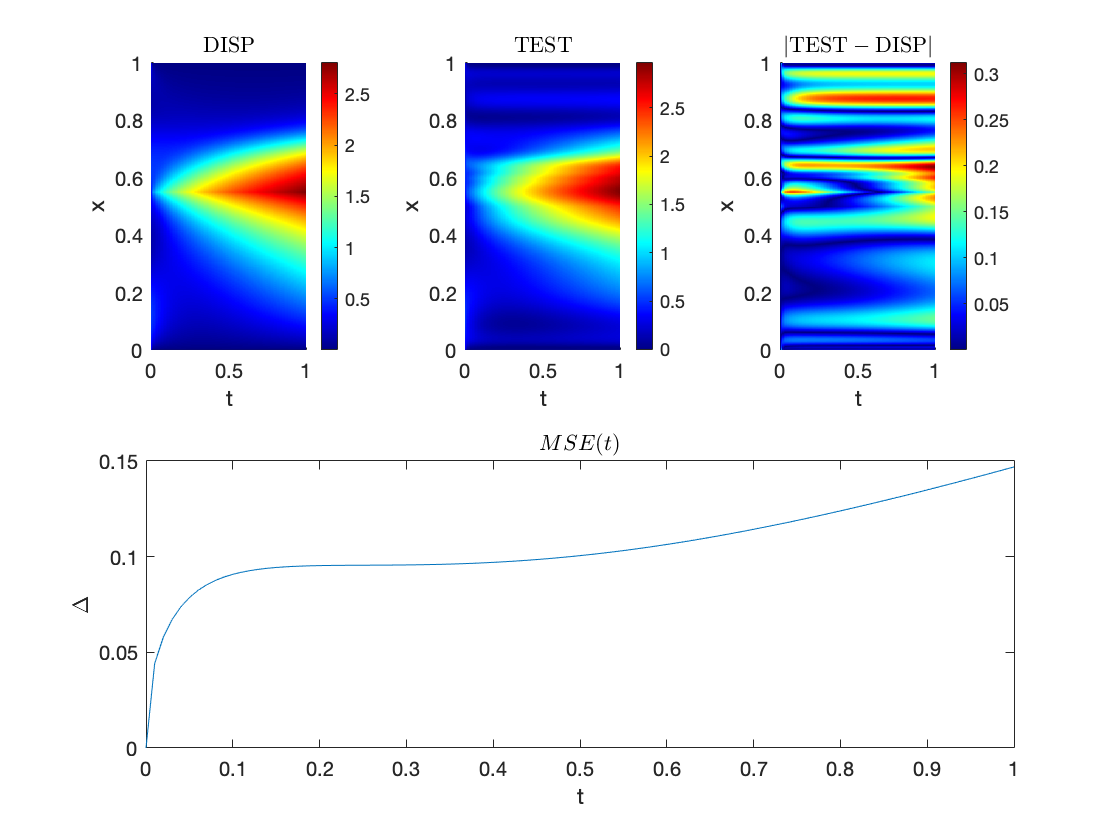

DMD = TEST;
DMD.X = real(e2.G);
plotComp(figure(),DISP,DMD);

- Compare $\text{ROM}_1(\tilde{D}_0),~\text{ROM}_1(D_0)$

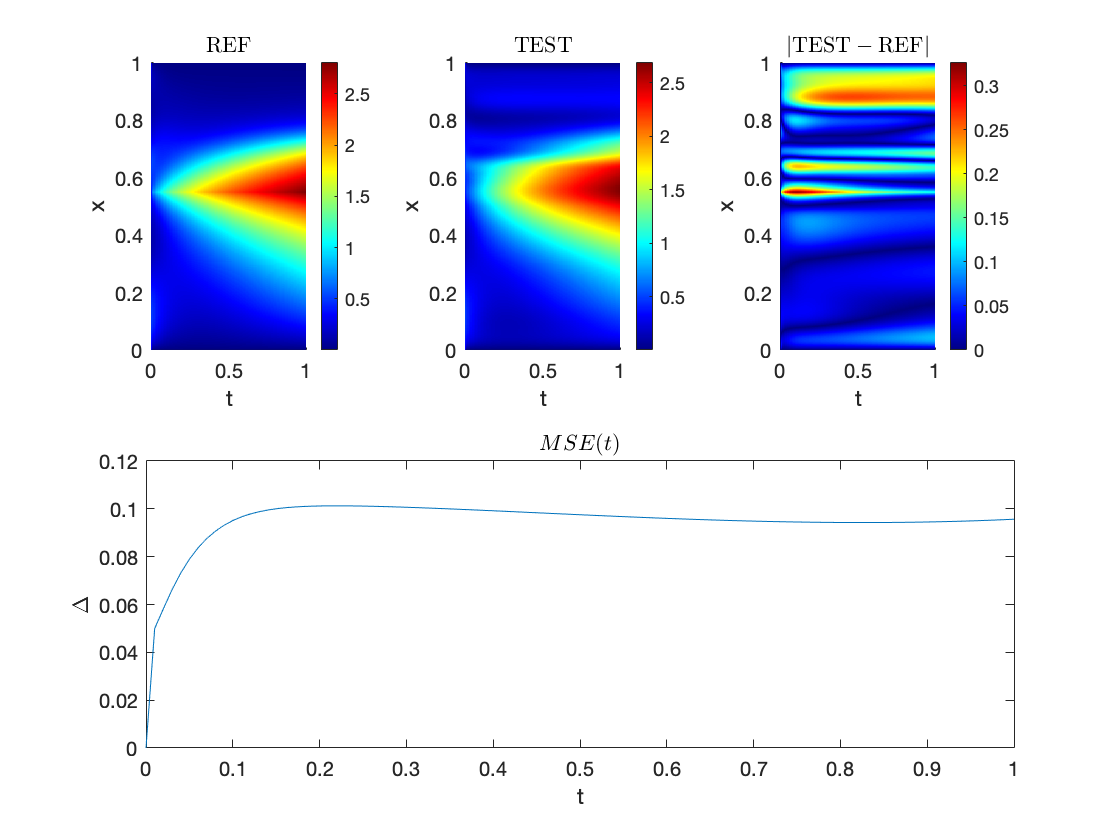

plotComp(figure(),REF,TEST);

# Next: eDMD and Gappy

## Fundamental solution analysis

%% Analytical solution
% % generate linear matrix
% J = buildJacobian(zeros(Nx,2),1,problem.param);
% % u_t + Jx * u = q
% Jx = full([J.Jx,J.Jxb;zeros(2,Nx+2)]);
% % evaluate
% exact = problem.sol;
% X = calcGreenODE(Jx,[x0;bc.state(:,2)],problem.sol.t,-[problem.param.q.val;0;0]);
% exact.X = X(1:end-2,:);
% plotComp(exact, problem.sol, D, fig); fig;